%计算考虑化学作用后的三锁体系
clear all
syms e r o;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=3.5;

%e=2000
%计算锁死所占成分
fun1 = @(x2,x1) P(x2).^2.*P(x1-x2).^2.*P(l-x1);
x2max= @(x1) x1;
V_lock = 3*integral2(fun1,0,l,0,x2max);
%计算开放所占成分
fun2 = @(x2,x1) P(l-x1).*P(x1).*P(x1-x2).*P(l-x2).*P(x2);
x2max= @(x1) x1;
V_open = 2*integral2(fun2,0,l,0,x2max);
P_lock = V_lock/(V_lock + V_open)%计算锁死所占比例

P_lock = 0.9355

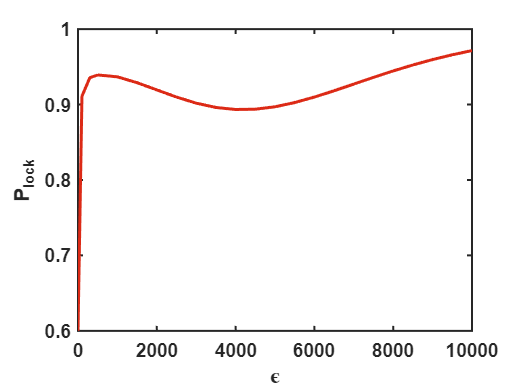



e=[0 100 300 500 1000 1500 2000 2500 3000 ...
    3500 4000 4500 5000 5500 6000 6500 ...
    7000 7500 8000 8500 9000 9500 10000];
Plock=[0.6 0.9109 0.9355 0.9392 0.9367 0.9289 0.9194 0.9099 0.9018 ...
    0.8961 0.8934 0.8938 0.8970 0.9026 0.9099 0.9182 ...
    0.9271 0.9360 0.9445 0.9524 0.9596 0.9659 0.9715];
plot(e, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)
set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('\epsilon','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=300;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

